% Set config
addpath('../');
c= Config.Testing();

% Create a camera object to take a picture  of displayed result.
take_pic= false;
if take_pic
    cam= Cam(1,'timeout',Inf);
end

% Make DHOT class to drive SLM
focal_length= 244; % effective focal length of setup
slm= DHOT(c, 'f', focal_length);

% Add vortices
points= [0 0;0,0.4];
L= [15,12];
dz= [0,0];
slm.add_vortex(points,L,dz);

 

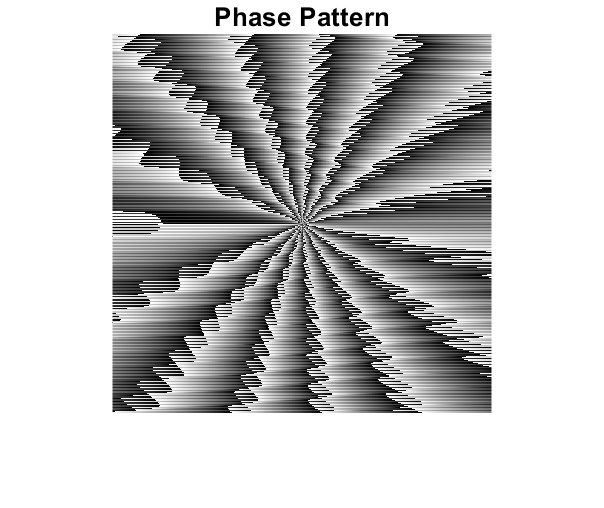

% Set parameters & run
alpha= 0.5;
N= 10;
use_gpu= false;

pattern= slm.compute_tweezers('alpha', alpha, 'use_gpu', use_gpu, 'N', N);

% Create imagesc of incident
figure(1);
imshow(mod(pattern,1));
title("Phase Pattern")

% Display image
disp('Displayed to SLM:')

Displayed to SLM:


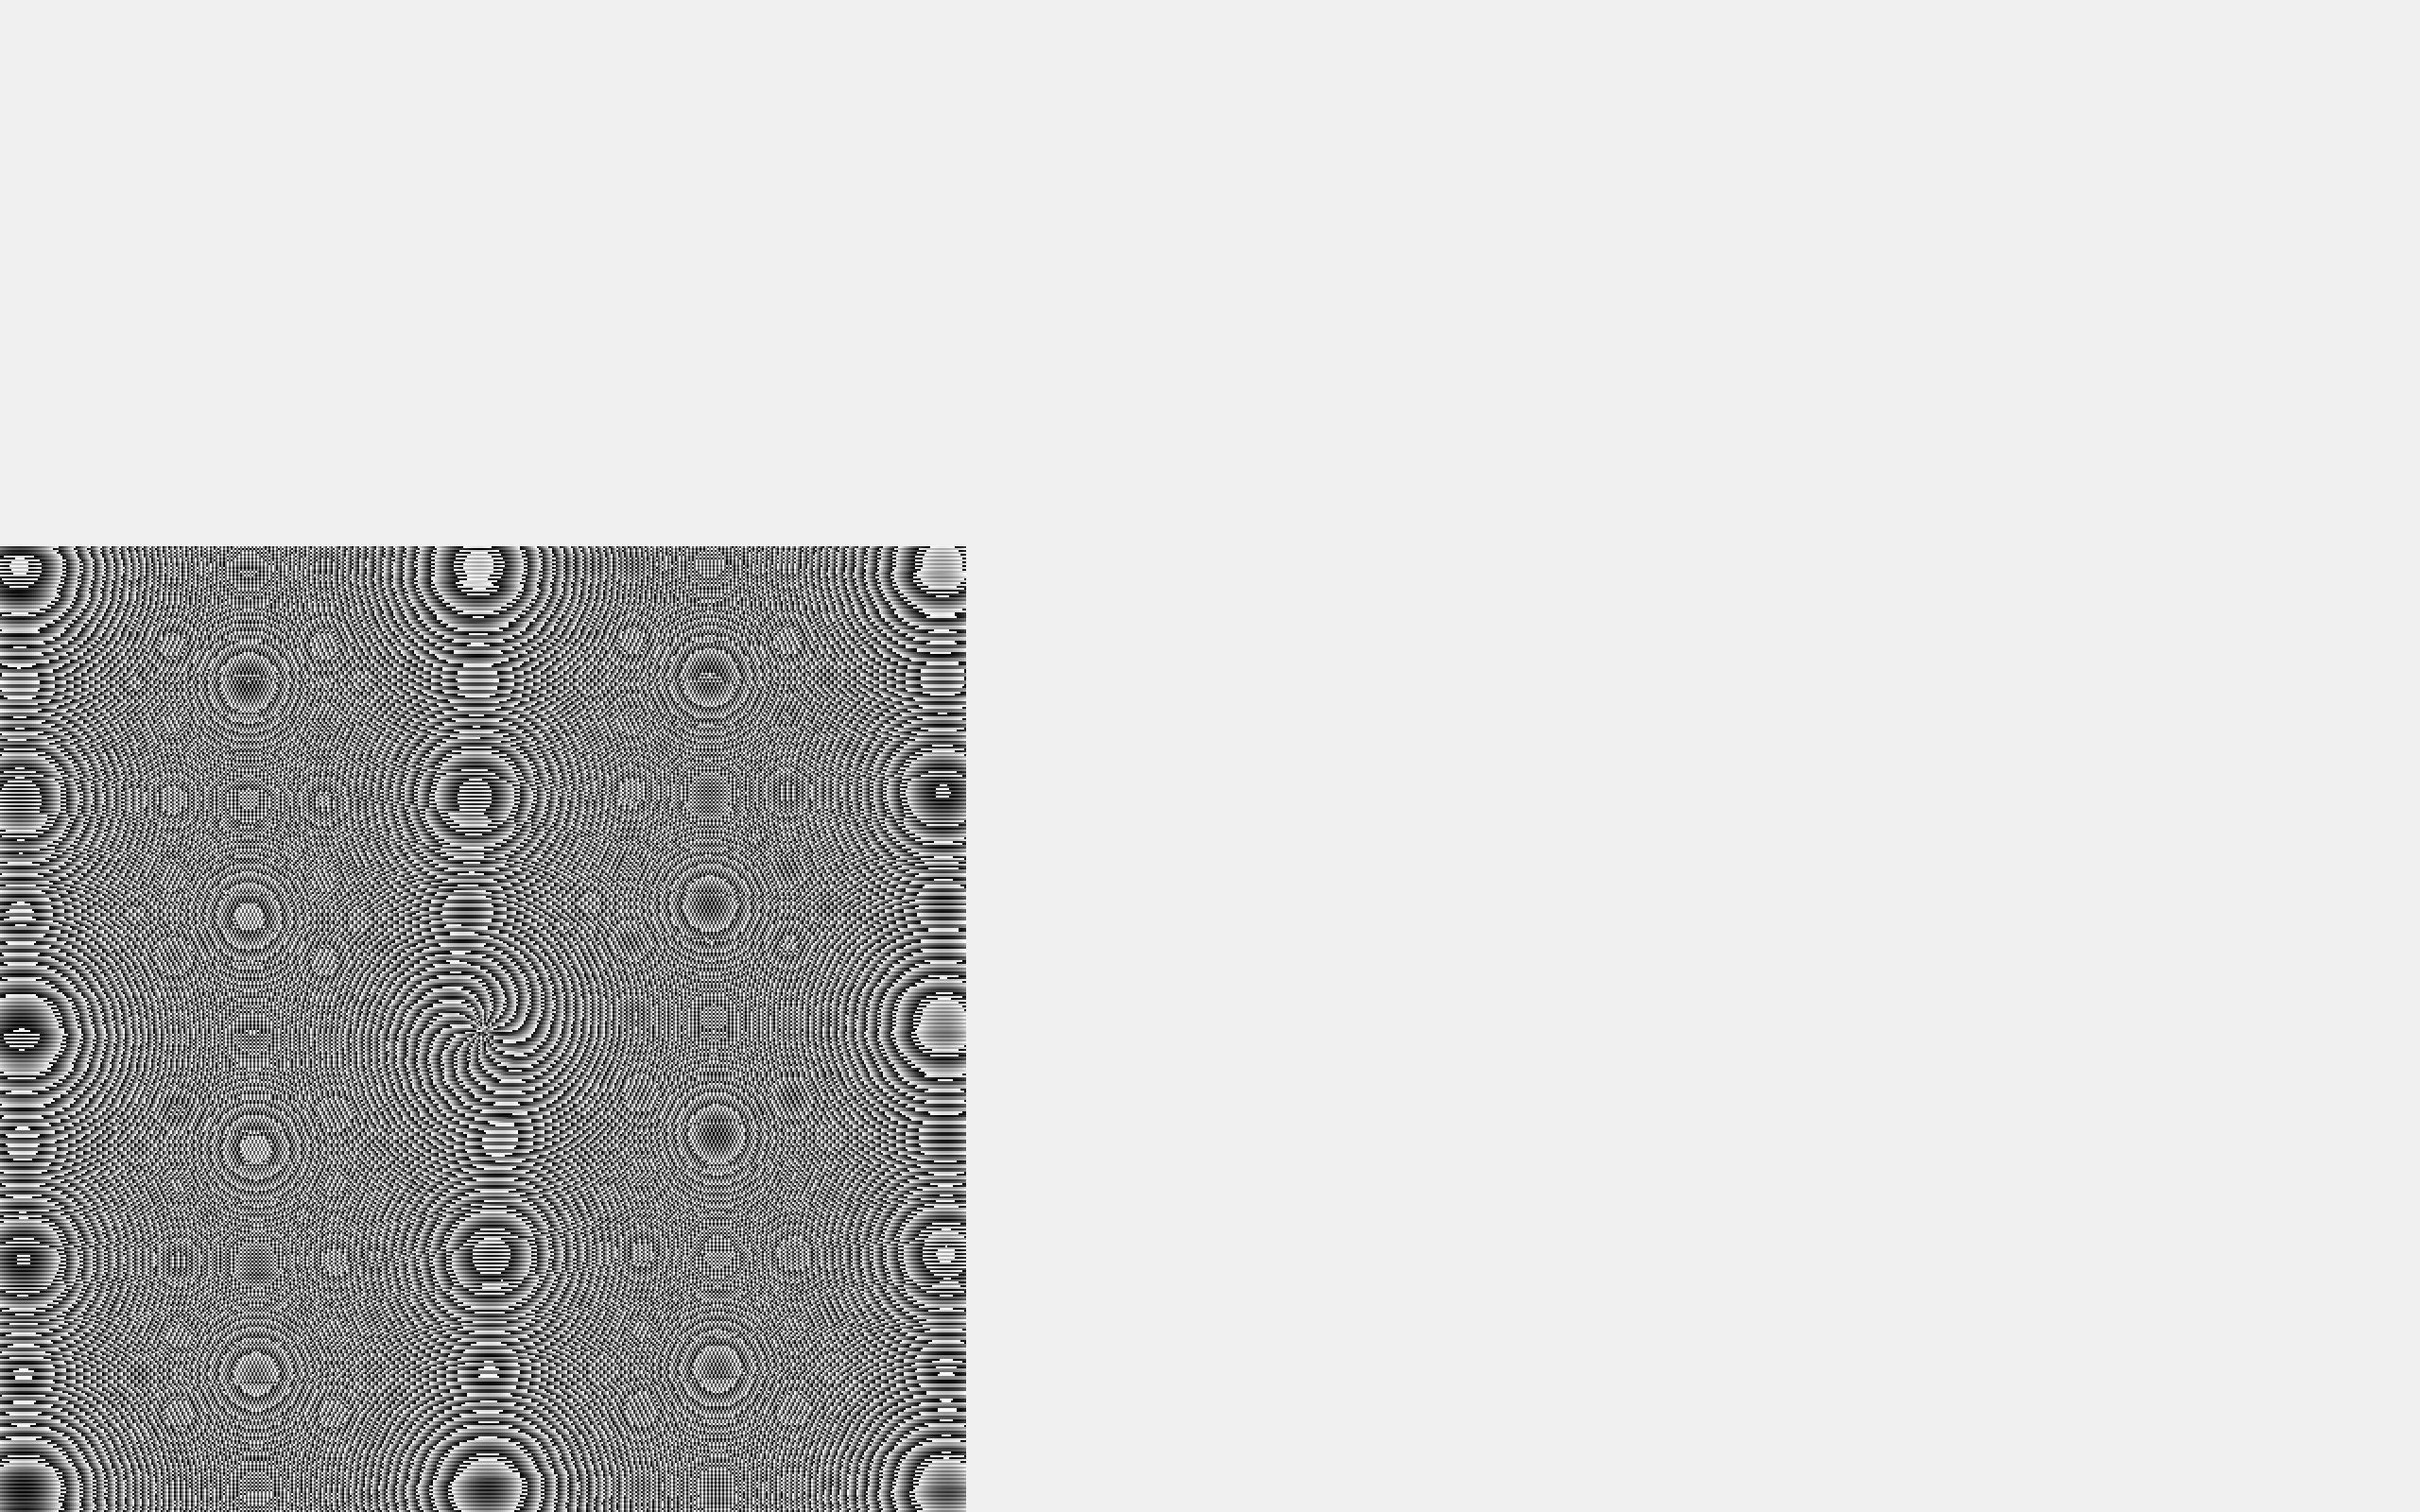

slm.show(pattern);


% Take picture
if take_pic
    pic= cam.capture();
    figure(2);
    imshow(pic)
    title("Result")
end
 

slm.reset();
 